# SJ - laboratorium 

## Termin 2 - Elementy statystyki w SJ

25.11.2024, g. 15:30 - 17:45, s. 623a.

Podsekcja:

Imię i nazwisko1 

Imię i nazwisko 2

## Zad.1.

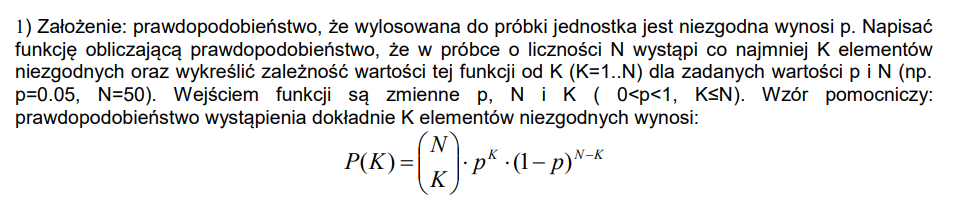

Napisać i wykorzystać w poniższym kodzie funkcję P=lab2_zad1(p,N,K), która oblicza prawdopodobieństwo, że co najmniej K elementów w próbce N-elementowej będzie niezgodnych. Funkcję wykorzystać do wykreślenia zależności dla K = 1...N.

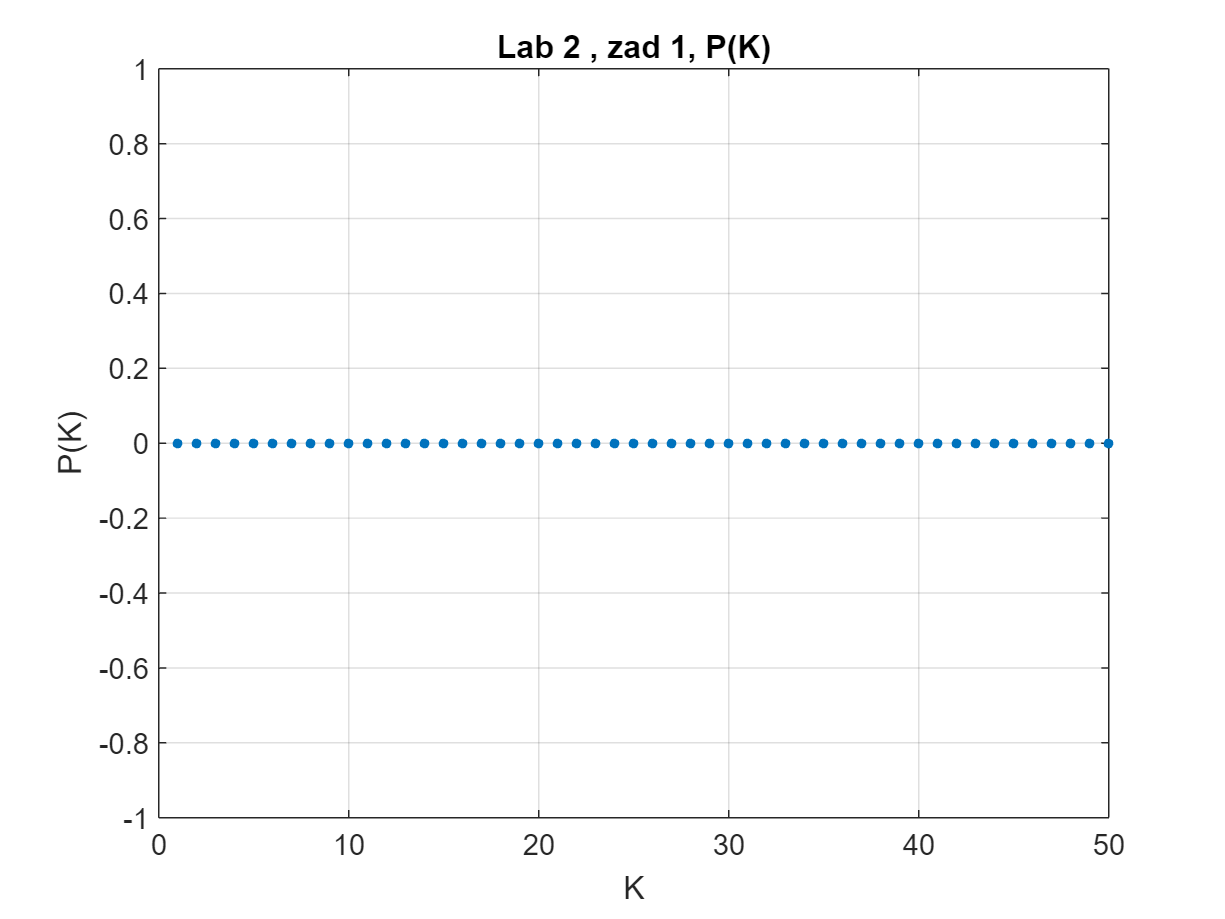

N=50;
p=0.5;
for K=1:N
P(K)=lab2_zad1(p,N,K);    
end  
figure;
plot(P,'.','MarkerSize',10);grid on;
title('Lab 2 , zad 1, P(K)');xlabel('K');ylabel('P(K)')

## Zad.2.

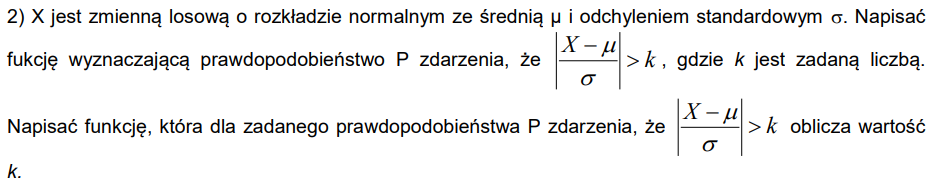

W zadaniu opisano zmienną znormalizowaną, to znaczy taką, że ma wartość średnią 0 i odchylenie standardowe 1.

Należy wykorzystać funkcje norminv i normcdf

%help norminv
%help normcdf
disp('Lab 2, Zad2 wyniki:')

Lab 2, Zad2 wyniki:


k=3

k = 3

P=lab2_zad2a(k)

P = 0

k1=lab2_zad2b(P)

k1 = 0

## Zad.3. 

 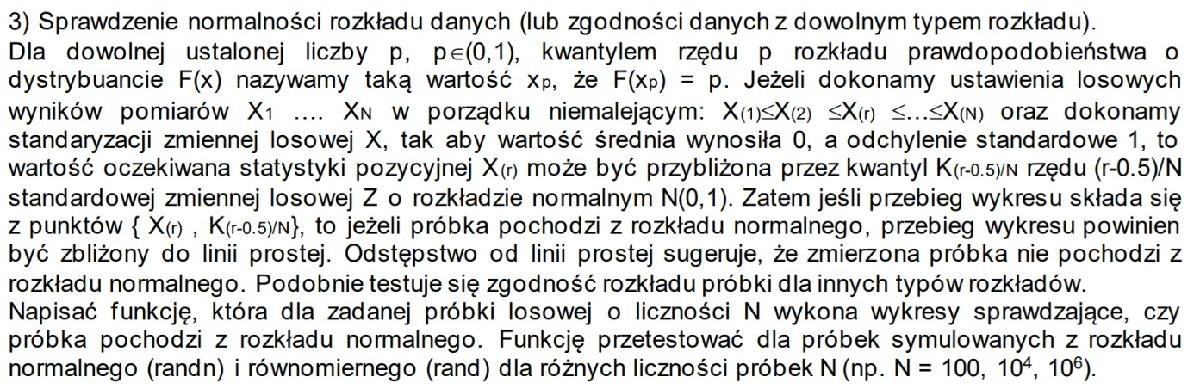

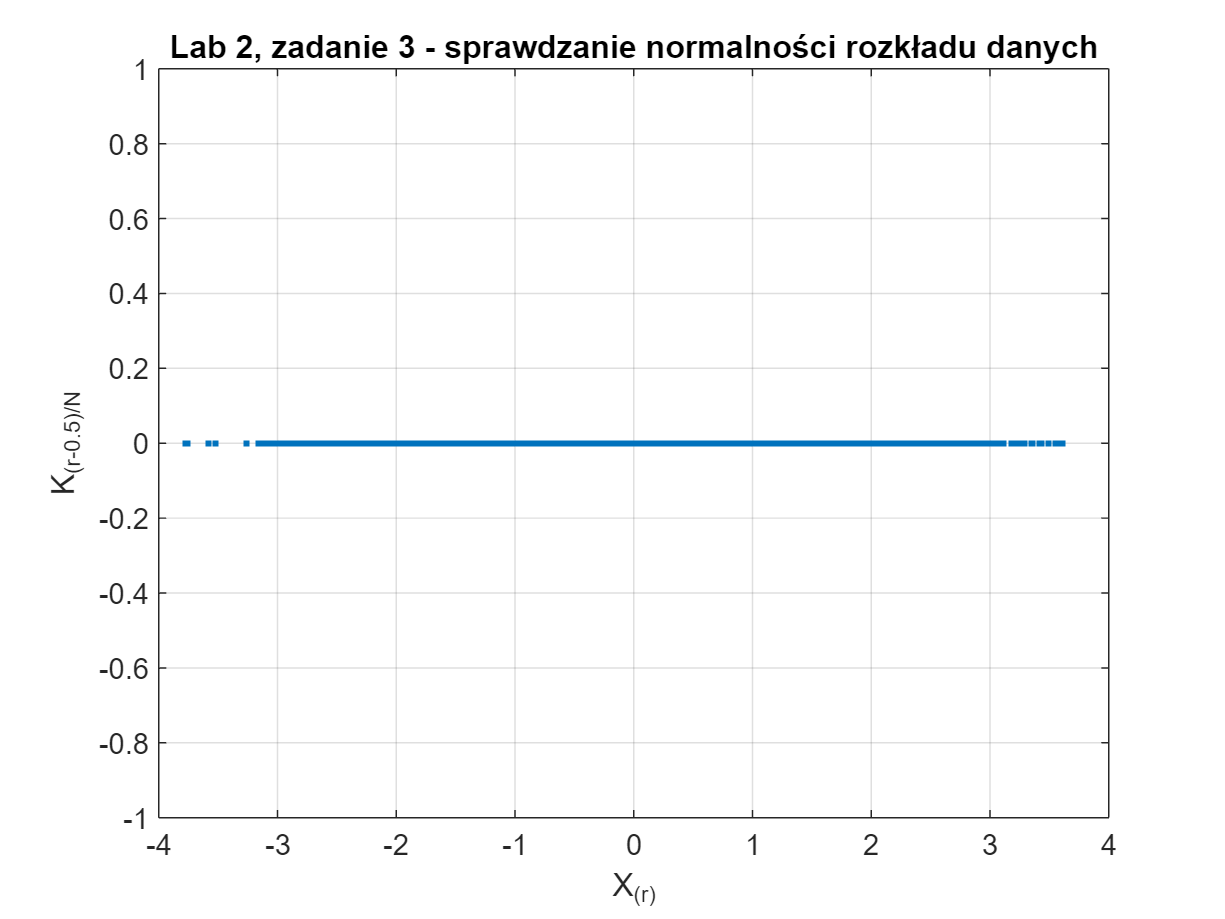

X=randn(10000,1);
[Xr, K]=lab2_zad3(X);
figure;
plot(Xr,K,'.'); xlabel('X_{(r)}');ylabel('K_{(r-0.5)/N}');grid on;
title('Lab 2, zadanie 3 - sprawdzanie normalności rozkładu danych')

## Zad. 4.

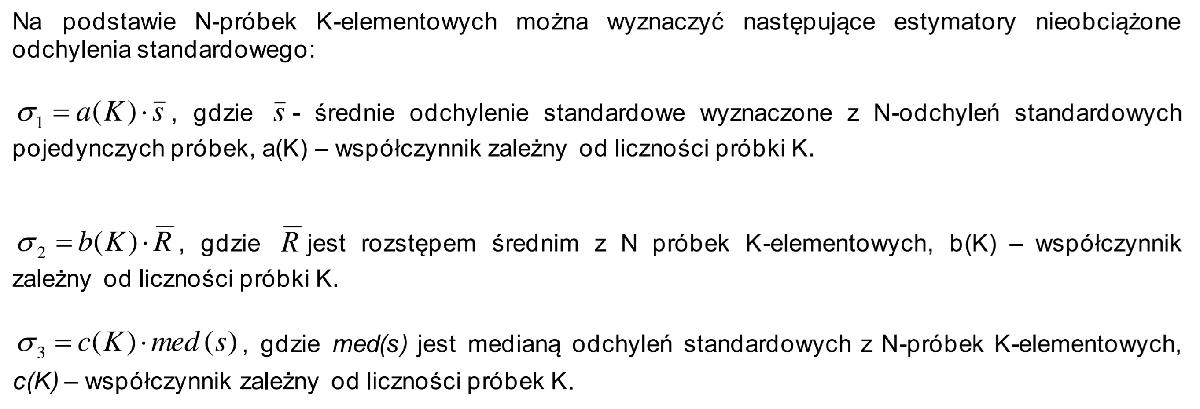

Funkcja [s1 s2 s3]=lab2_zad4(X) oblicza zadane estymatory. Zobaczmy jakie są wyniki:

K=10;N=5

N = 5

mi=0;sigma=1;
X=randn(K,N)*sigma+mi; % 5 próbek 10-elementowych
[s1 s2 s3]=lab2_zad4(X)

s1 = 0

s2 = 0

s3 = 0


% Badanie efektywności estymatorów:
% Napierw trzeba wyznaczyć wariancje estymatorów dla dużej próbki:

S=[]


S =

     []



Nrealiz=10000; % liczba realizacji każdego estymatora 
for i=1:Nrealiz
X=randn(K,N);
[s1 s2 s3]=lab2_zad4(X);
S=[S; [s1 s2 s3]];
end

VS=var(S)

VS =      0     0     0


## Zad. 5.

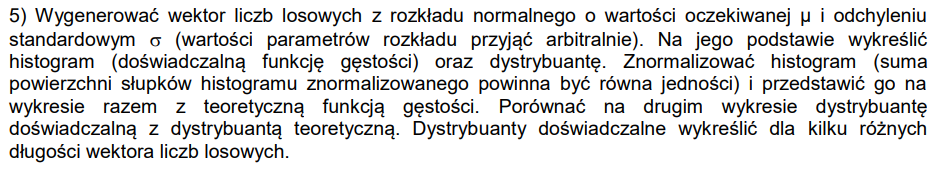

Przydatny kod:

[N,X] = hist(randn(1000,1)*sigma+mi,k) also returns in X the position of the bin centers for

    numeric data, or the categories corresponding to N for categorical

    data.

mi=5;sig=10;
X=randn(100000,1)*sig+mi;
liczba_binow=31;
wy=lab2_zad5(X,liczba_binow,mi,sig)

wy = 'Wszystko ok'

## Funkcje realizujące zadania:

function P=lab2_zad1(p,N,K)
% P - prawdopodobieństwo, że conajmniej K elementów będzie niezgodnych;
P=0;

end % P=lab2_zad1(p,N,K)


% Zad 2. 
function P=lab2_zad2a(k)
P=0; % obliczyć poprawnie P
end % of P=lab2_zad2a(k)


function k=lab2_zad2b(P)
k=0; % obliczyć poprawnie k
end % of k=lab2_zad2b(P)



% Zad 3.

function [Xr, K]=lab2_zad3(X);

X=(X-mean(X))/std(X);
Xr=sort(X);
N=length(X);

% Tu obliczyć wartości wektora kwantyli K o rzędach (r-0.5)/N
K=zeros(size(Xr));


end % of [Xr, K]=lab2_zad3(X);





% Zad 4.

function [s1 s2 s3]=lab2_zad4(X)

% X - N próbek K-elementowych, próbki ustawione w kolejnych kolumnach
[K, N]=size(X);

% Tabelka z zadania:
I=[2 3 4 5 6 7 8 9 10 15 20];
a=[1.253 1.1284 1.0854 1.0638 1.0510 1.0423 1.0363 1.0317 1.0281 1.0180 .0133];
b=[0.8865 0.5907 0.4857 0.43 0.3946 0.3698 0.3512 0.3367 0.3249 0.288 0.2677];
c=[1.1829 1.0646 1.0374 1.0260 1.0201 1.0161 1.0136 1.0116 1.0103 1.0063 1.0046];

% Poniżej poprawnie wyznaczyć wartości estymatorów s1, s2 i s3:
s1=0;
s2=0;
s3=0;

end % of [s1 s2 s3]=lab2_zad4(X)


% Zad 5
function wy=lab2_zad5(X,liczba_binow,mi,sig)

[N,px]=hist(X,liczba_binow); % chcemy mieć dużo binów. N - liczba zliczeń w każdym binie; px - położenie środka binu.
dx=px(2)-px(1); % szerokość binów.
% powierzchnia histogramu = sum(N)*dx

% Przeprowadzić odpowiednie normalizacje i narysować 3 wykresy:
% 1) surowy histogram
% 2) znormalizowany histogram (powierzchnia = 1) wraz z teoretyczną funkcją
% gęstości
% 3) histogram dystrybuanty wraz z dystrybuantą  teoretyczną.

wy='Wszystko ok';
end % of lab2_zad5()